
mouse_all=["1610","1611","1612","1626","1627","1629","1630"]

mouse_all = 1×7 string array
    "1610"    "1611"    "1612"    "1626"    "1627"    "1629"    "1630"


mouseID = ["1610",
     "1611",
    "1612",
    "1627",
    "1629",
    "1630",
    "1626",
%     #"1626",
    "1627",
%     #"1627",
    "1610",
    "1612",
%     #"1626",
%     #"1611",
%     #"1612",
    "1629",
    "1629",
    "1630",
    "1630"]

mouseID = 14×1 string array
    "1610"
    "1611"
    "1612"
    "1627"
    "1629"
    "1630"
    "1626"
    "1627"
    "1610"
    "1612"
    "1629"
    "1629"
    "1630"
    "1630"



laser = ["1",
    "1",
    "1",
    "1",
    "1",
    "1",
    "1",
%     #"2",
    "2",
%     #"3",
    "3",
    "2",
%     #"3",
%     #"1",
%     #"3",
    "2",
    "3",
    "2",
    "3"]

laser = 14×1 string array
    "1"
    "1"
    "1"
    "1"
    "1"
    "1"
    "1"
    "2"
    "3"
    "2"
    "2"
    "3"
    "2"
    "3"


cd('/Users/pingchuanma/Desktop/ChenLab_Data/RvR')



% running as 1, resting as 0
lft_all=[];
intensity_all=[];
animalID_all=[];
laser_all=[];
states_all=[];
speed_all=[];


for i=1:14
    mouse=find(mouse_all==mouseID(i));
    laserpower=str2num(laser(i));

    runningcsvfile=['runningDictsOutput',num2str(i-1),'.csv'];
    runningoutput=csvread(runningcsvfile,1,0);
    running_speed_csvfile=['speedOutput',num2str(i-1),'.csv'];
    running_speed_output=csvread(running_speed_csvfile,1,0);
    running_speed_output(:,1)=[];
    running_speed=[];
    for j=1:size(running_speed_output,1)
        running_speed(j,1)=max(running_speed_output(j,:));
    end
    j
    running_lft=runningoutput(:,8);
    running_intensity=runningoutput(:,2);
    n=length(running_lft)
    lft_all=[lft_all;running_lft];
    intensity_all=[intensity_all;running_intensity];
    animalID_all=[animalID_all;zeros(n,1)+mouse];
    laser_all=[laser_all;zeros(n,1)+laserpower];
    states_all=[states_all;zeros(n,1)+1];
    speed_all=[speed_all;running_speed];



    restingcsvfile=['baselineDictsOutput',num2str(i-1),'.csv'];
    restingoutput=csvread(restingcsvfile,1,0);
    resting_lft=restingoutput(:,8);
    resting_intensity=restingoutput(:,2);
    n=length(resting_lft);
    lft_all=[lft_all;resting_lft];
    intensity_all=[intensity_all;resting_intensity];
    animalID_all=[animalID_all;zeros(n,1)+mouse];
    laser_all=[laser_all;zeros(n,1)+laserpower];
    states_all=[states_all;zeros(n,1)];
    speed_all=[speed_all;zeros(n,1)];

   

    
end

j = 31

n = 31

j = 45

n = 45

j = 12

n = 12

j = 13

n = 13

j = 58

n = 58

j = 43

n = 43

j = 29

n = 29

j = 18

n = 18

j = 6

n = 6

j = 24

n = 24

j = 67

n = 67

j = 35

n = 35

j = 52

n = 52

j = 32

n = 32


intensity_all=intensity_all/100000;


lft1610=lft_all(find(animalID_all==1));
intensity1610=intensity_all(find(animalID_all==1));
speed1610=speed_all(find(animalID_all==1));
laser1610=laser_all(find(animalID_all==1));
states1610=states_all(find(animalID_all==1));

lft1610_1=lft1610(find(laser1610==1));
intensity1610_1=intensity1610(find(laser1610==1));
speed1610_1=speed1610(find(laser1610==1));
states1610_1=states1610(find(laser1610==1));
lft1610_1_running=lft1610_1(find(states1610_1==1));
lft1610_1_resting=lft1610_1(find(states1610_1==0));
intensity1610_1_running=intensity1610_1(find(states1610_1==1));
intensity1610_1_resting=intensity1610_1(find(states1610_1==0));


lft1610_2=lft1610(find(laser1610==3));
intensity1610_2=intensity1610(find(laser1610==3));
speed1610_2=speed1610(find(laser1610==3));
states1610_2=states1610(find(laser1610==3));
lft1610_2_running=lft1610_2(find(states1610_2==1));
lft1610_2_resting=lft1610_2(find(states1610_2==0));
intensity1610_2_running=intensity1610_2(find(states1610_2==1));
intensity1610_2_resting=intensity1610_2(find(states1610_2==0));

intensity_collection=[];
mouseID_collection=[];
laser_collection=[];
states_collection=[];

for i=1:7
    mouse=mouse_all(i)
    

    lft_mouse=lft_all(find(animalID_all==i));
    intensity_mouse=intensity_all(find(animalID_all==i));
    speed_mouse=speed_all(find(animalID_all==i));
    laser_mouse=laser_all(find(animalID_all==i));
    states_mouse=states_all(find(animalID_all==i));

    eval(['lft_',convertStringsToChars(mouse),'=lft_mouse;'])
    eval(['intensity_',convertStringsToChars(mouse),'=intensity_mouse;'])
    eval(['speed_',convertStringsToChars(mouse),'=speed_mouse;'])
    eval(['laser_',convertStringsToChars(mouse),'=laser_mouse;'])
    eval(['states_',convertStringsToChars(mouse),'=states_mouse;'])

    for j=1:3

        lft_mouse_laser=lft_mouse(find(laser_mouse==j));
        intensity_mouse_laser=intensity_mouse(find(laser_mouse==j));
        speed_mouse_laser=speed_mouse(find(laser_mouse==j));
        states_mouse_laser=states_mouse(find(laser_mouse==j));
        lft_mouse_laser_running=lft_mouse_laser(find(states_mouse_laser==1));
        lft_mouse_laser_resting=lft_mouse_laser(find(states_mouse_laser==0));
        intensity_mouse_laser_running=intensity_mouse_laser(find(states_mouse_laser==1));

        mouseID_collection=[mouseID_collection;str2num(mouse)];
        laser_collection=[laser_collection;j];
        states_collection=[states_collection;[1]];
        if isempty(intensity_mouse_laser_running)
            intensity_collection=[intensity_collection;[NaN]];
        else
            intensity_collection=[intensity_collection;mean(intensity_mouse_laser_running)];
        end

        intensity_mouse_laser_resting=intensity_mouse_laser(find(states_mouse_laser==0));

        mouseID_collection=[mouseID_collection;str2num(mouse)];
        laser_collection=[laser_collection;[j]];
        states_collection=[states_collection;[0]];
        if isempty(intensity_mouse_laser_resting)
            intensity_collection=[intensity_collection;[NaN]];
        else
            intensity_collection=[intensity_collection;mean(intensity_mouse_laser_resting)];
        end

        
        

        eval(['lft_',convertStringsToChars(mouse),'_',num2str(j),'=lft_mouse_laser;'])
        eval(['intensity_',convertStringsToChars(mouse),'_',num2str(j),'=intensity_mouse_laser;'])
        eval(['speed_',convertStringsToChars(mouse),'_',num2str(j),'=speed_mouse_laser;'])
        eval(['states_',convertStringsToChars(mouse),'_',num2str(j),'=states_mouse_laser;'])

        eval(['lft_',convertStringsToChars(mouse),'_',num2str(j),'_running','=lft_mouse_laser_running;'])
        eval(['lft_',convertStringsToChars(mouse),'_',num2str(j),'_resting','=lft_mouse_laser_resting;'])
        eval(['intensity_',convertStringsToChars(mouse),'_',num2str(j),'_running','=intensity_mouse_laser_running;'])
        eval(['intensity_',convertStringsToChars(mouse),'_',num2str(j),'_resting','=intensity_mouse_laser_resting;'])
    end

end

mouse = "1610"

mouse = "1611"

mouse = "1612"

mouse = "1626"

mouse = "1627"

mouse = "1629"

mouse = "1630"


FYI=[mouseID_collection laser_collection states_collection intensity_collection];

        




figure1=figure;
figure1.Position=[10 10 500 400];

scatter(speed1610_1,lft1610_1,'filled')
hold on
scatter(speed1610_2,lft1610_2,'filled')
hold off
legend('Laser1','Laser2','FontSize',24)
xlabel('Speed (cm/s)')
xlim([-0.5 18])
xticks([0 5 10 15])
ylabel('Lifetime (ns)')
ylim([4.15 4.3])
yticks([4.15 4.2 4.25])
ax=gca

ax =   Axes with properties:

             XLim: [-0.500000000000000 18]
             YLim: [4.150000000000000 4.300000000000000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.130000000000000 0.110000000000000 0.775000000000000 0.815000000000000]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [-0.500000000000000 18]
             YLim: [4.150000000000000 4.300000000000000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.176600000000000 0.169499481836958 0.728400000000000 0.755500518163042]
            Units: 'normalized'

  Show all properties


ax.FontSize=24


figure2=figure;
figure2.Position=[10 10 500 400];

scatter(speed1610_1,intensity1610_1,'filled')
hold on
scatter(speed1610_2,intensity1610_2,'filled')
hold off
% legend('Laser1','Laser2')
xlabel('Speed (cm/s)')
xlim([-0.5 18])
xticks([0 5 10 15])
ylabel('Intensity')
ylim([2.50000 4.50000])
% yticks([250000 350000 450000])
ax=gca

ax =   Axes with properties:

             XLim: [-0.500000000000000 18]
             YLim: [2.500000000000000 4.500000000000000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.130000000000000 0.110000000000000 0.775000000000000 0.815000000000000]
            Units: 'normalized'

  Show all properties


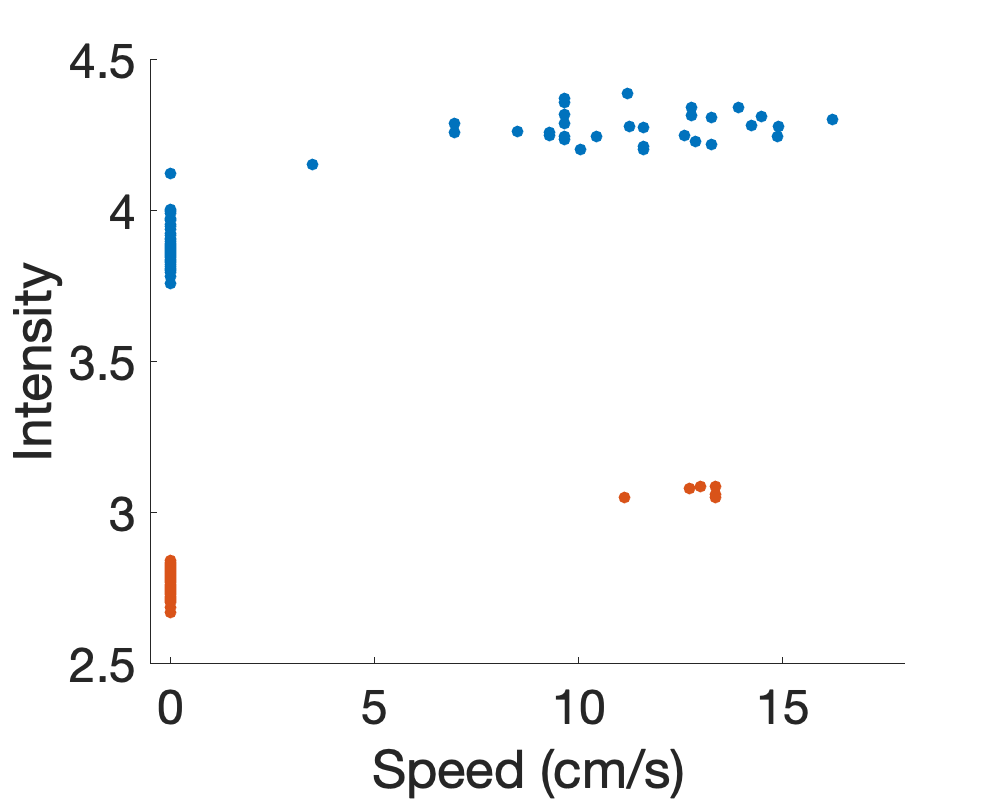

ax =   Axes with properties:

             XLim: [-0.500000000000000 18]
             YLim: [2.500000000000000 4.500000000000000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.149600000000000 0.169500000000000 0.755400000000000 0.755500000000000]
            Units: 'normalized'

  Show all properties


ax.FontSize=24

% Transform the categorical variables to dummy variables

states_all_categorical=categorical(states_all);
states_all_dv=dummyvar(states_all_categorical);
categories(states_all_categorical)

ans = 2×1 cell array
    {'0'}
    {'1'}



animalID_all_categorical=categorical(animalID_all);
animalID_all_dv=dummyvar(animalID_all_categorical);
categories(animalID_all_categorical)

ans = 7×1 cell array
    {'1'}
    {'2'}
    {'3'}
    {'4'}
    {'5'}
    {'6'}
    {'7'}



laser_all_categorical=categorical(laser_all);
laser_all_dv=dummyvar(laser_all_categorical);
categories(laser_all_categorical)

ans = 3×1 cell array
    {'1'}
    {'2'}
    {'3'}


% creat table for glm analysis, use the predictors as categorical
% By default, fitglm takes the last variable as the response variable and the others as the predictor variables
% If data is in a table or dataset array tbl, then, by default, 
% fitglm treats all categorical values, logical values, character arrays, 
% string arrays, and cell arrays of character vectors as categorical variables.

lft_tbl=table(states_all_categorical,animalID_all_categorical,laser_all_categorical,lft_all)
intensity_tbl=table(states_all_categorical,animalID_all_categorical,laser_all_categorical,intensity_all)

mdl1=fitglm(lft_tbl)

mdl1 = Generalized linear regression model:
    lft_all ~ 1 + states_all_categorical + animalID_all_categorical + laser_all_categorical
    Distribution = Normal

Estimated Coefficients:
                                   Estimate        SE         tStat       pValue  
                                  __________    _________    _______    __________

    (Intercept)                       4.1968    0.0012711     3301.7             0
    states_all_categorical_1        0.054862    0.0009728     56.396             0
    animalID_all_categorical_2     0.0018414    0.0020313    0.90652       0.36483
    animalID_all_categorical_3     0.0090994    0.0016711      5.445    6.1945e-08
    animalID_all_categorical_4    -0.0065388    0.0020099    -3.2533     0.0011701
    

mdl2=fitglm(intensity_tbl)

mdl2 = Generalized linear regression model:
    intensity_all ~ 1 + states_all_categorical + animalID_all_categorical + laser_all_categorical
    Distribution = Normal

Estimated Coefficients:
                                  Estimate       SE        tStat       pValue   
                                  ________    ________    _______    ___________

    (Intercept)                    4.1945     0.030408     137.94              0
    states_all_categorical_1      0.43145     0.023272     18.539     3.2076e-68
    animalID_all_categorical_2    -2.3305     0.048594    -47.959    3.6869e-289
    animalID_all_categorical_3     1.2331     0.039979     30.844    5.3581e-157
    animalID_all_categorical_4    -1.4612     0.048083     -30.39    1.7014e-153
    animal

% Trying to see whether numbers of these categorical variables matter
% I'm changing the running vs resting from 1 vs 0 to 1 vs 2.
states_all2=states_all;
states_all2(find(states_all2==1))=2;
states_all2_categorical=categorical(states_all2);
categories(states_all2_categorical)

lft_tbl=table(states_all2_categorical,animalID_all_categorical,laser_all_categorical,lft_all)
intensity_tbl=table(states_all2_categorical,animalID_all_categorical,laser_all_categorical,intensity_all)

mdl3=fitglm(lft_tbl)
mdl4=fitglm(intensity_tbl)

states_all2=states_all;
states_all2(find(states_all2==0))=2;
states_all2_categorical=categorical(states_all2);
categories(states_all2_categorical)

lft_tbl=table(states_all2_categorical,animalID_all_categorical,laser_all_categorical,lft_all)
intensity_tbl=table(states_all2_categorical,animalID_all_categorical,laser_all_categorical,intensity_all)

mdl3=fitglm(lft_tbl)
mdl4=fitglm(intensity_tbl)